# Spring Rate Calculations

To calculate all necesary parameters for spring rate calculations.

fn_front = 1.2; % Required Ride Frequency front
fn_rear = 1.4; % Required Ride Frequency Rear
wf = 0.45*230; % Front Weight (kg)
wr = 0.55*230; % Rear Weight (kg)
tf = 58; % Front Trackidth in inches
tr = 56; % Rear Trackwidth in inches
MRf = 0.58; % Motion Ratio Front
MRr = 0.6; % Motion Ratio Rear
kt = 50000; % Tire Stiffness (N/m)
ms = 180; % Sprung Mass (kg)
mu = 50; % Unsprung Mass (kg)

muf = 50/4; % Unsprung mass front single suspension unit
mur = 50/4; % Unsprung mass rear single suspension unit

msf = 0.45*ms/2; % Sprung mass on single suspension in front
msr = 0.55*ms/2; % Sprung mass on a single suspension in rear
% kt = kt*1000;
tf = tf*25.4/1000;
tr = tr*25.4/1000;

## Wheel Rates

krf = ((fn_front*2*pi)^2)*wf/2; % Wheel Rate front
krr = ((fn_rear*2*pi)^2)*wr/2; % Wheel Rate rear

## Spring Rates

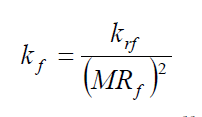

kf = krf/(MRf)^2; % Spring Rates Front
kr = krr/(MRr)^2; % Spring Rates Rear

## Roll Rates

**Note: kr is in lb/in acc to equation, we'll be using N/m**

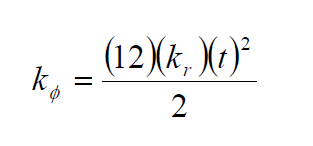

roll_rate_front_rad = (tf^2)*kf/2; % Front Roll Rate in Radians
roll_rate_front_deg = roll_rate_front_rad*2*pi/360; % Front Roll Rate in Degrees

roll_rate_rear_rad = (tr^2)*kr/2; % Rear Roll Rate in Radians
roll_rate_rear_deg = roll_rate_rear_rad*2*pi/360; % Rear Roll Rate in Degrees

## Natural Frequency

The frequencies can be approximated by the following equations (The natural frequency of the both the unsprung and sprung mass in hertz).

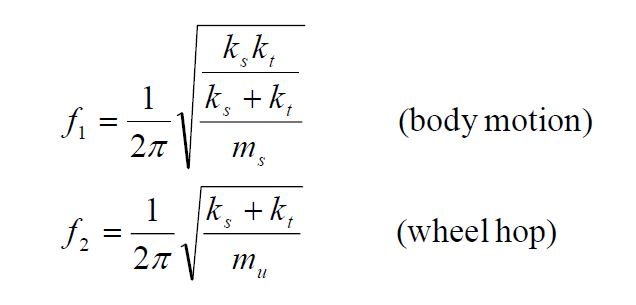

f1_f = (1/(2*pi))*sqrt((kf*kt)/((kf+kt)/msf));
f1_r = (1/(2*pi))*sqrt((kr*kt)/((kr+kt)/msr));

f2_f = (1/(2*pi))*sqrt((kf + kt)/muf);
f2_r = (1/(2*pi))*sqrt((kr + kr)/mur);

## Critical Damping at the Wheel

Crit_f = 2*sqrt(krf * msf);
Crif_r = 2*sqrt(krr * msr);